clear all

clc


## Problem1 State Space Model of DIPC

% this code continous the hand derviation of the EoM in matlab 

%%Define Variables
% VAriables

syms M m1 m2 l1 l2 g
syms theta1 theta2 x_pos theta1_dot theta2_dot x_dot theta1_ddot theta2_ddot x_ddot
syms u

disp("Lagraian EoM from Hand derviation convertered inCode")

Lagraian EoM from Hand derviation convertered inCode


% EOM --> x 
eq1 = (M + m1 + m2) * x_ddot ...
      + (m1 + m2) * l1 * theta1_ddot * cos(theta1) ...
      + m2 * l2 * theta2_ddot * cos(theta2) ...
      - (m1 + m2) * l1 * theta1_dot^2 * sin(theta1) ...
      - m2 * l2 * theta2_dot^2 * sin(theta2) ...
      - u == 0

$$eq1 = -l_{1}\,\sin\left(\theta_{1}\right)\,\left(m_{1}+m_{2}\right)\,{\theta_{\dot{1}}}^{2}-l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)\,{\theta_{\dot{2}}}^{2}-u+\ddot{x}\,\left(M+m_{1}+m_{2}\right)+l_{1}\,\theta_{\ddot{1}}\,\cos\left(\theta_{1}\right)\,\left(m_{1}+m_{2}\right)+l_{2}\,m_{2}\,\theta_{\ddot{2}}\,\cos\left(\theta_{2}\right)=0$$


% EOM --> theta1 
eq2 = (m1 + m2) * l1^2 * theta1_ddot...
      + (m1 + m2) * l1 * x_ddot * cos(theta1) ...
      + m2 * l1 * l2 * theta2_ddot * cos(theta1 - theta2) ...
      + m2 * l1 * l2 * theta2_dot^2 * sin(theta1 - theta2) ... 
      - (m1 + m2) * g * l1 * sin(theta1) == 0

$$eq2 = {l_{1}}^{2}\,\theta_{\ddot{1}}\,\left(m_{1}+m_{2}\right)-g\,l_{1}\,\sin\left(\theta_{1}\right)\,\left(m_{1}+m_{2}\right)+l_{1}\,\ddot{x}\,\cos\left(\theta_{1}\right)\,\left(m_{1}+m_{2}\right)+l_{1}\,l_{2}\,m_{2}\,\theta_{\ddot{2}}\,\cos\left(\theta_{1}-\theta_{2}\right)+l_{1}\,l_{2}\,m_{2}\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)=0$$


% EOM --> theta2 
eq3 = m2 * l2^2 * theta2_ddot ...
      + m2 * l2 * x_ddot * cos(theta2) ...
      + m2 * l1 * l2 * theta1_ddot * cos(theta1 - theta2) ...
      - m2 * l1 * l2 * theta1_dot^2 * sin(theta1 - theta2) ... 
      - m2 * g * l2 * sin(theta2) == 0

$$eq3 = {l_{2}}^{2}\,m_{2}\,\theta_{\ddot{2}}-g\,l_{2}\,m_{2}\,\sin\left(\theta_{2}\right)+l_{2}\,m_{2}\,\ddot{x}\,\cos\left(\theta_{2}\right)+l_{1}\,l_{2}\,m_{2}\,\theta_{\ddot{1}}\,\cos\left(\theta_{1}-\theta_{2}\right)-l_{1}\,l_{2}\,m_{2}\,{\theta_{\dot{1}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)=0$$


% statevector
state_vector = [x_pos; theta1; theta2; x_dot; theta1_dot; theta2_dot]

$$state\_vector = \left(\begin{array}{c} x_{\mathrm{pos}}\\ \theta_{1}\\ \theta_{2}\\ \dot{x}\\ \theta_{\dot{1}}\\ \theta_{\dot{2}} \end{array}\right)$$

input_vector = u

$$input\_vector = u$$


%Solve equations for higthes derviative
eqddot = solve([eq1, eq2, eq3], [x_ddot, theta1_ddot, theta2_ddot])

eqddot = struct with fields:
         x_ddot: -(m1*u + m2*u - m2*u*cos(theta1 - theta2)^2 - g*m1^2*cos(theta1)*sin(theta1) - g*m2^2*cos(theta1)*sin(theta1) - g*m2^2*cos(theta2)*sin(theta2) + l1*m1^2*theta1_dot^2*sin(theta1) + l1*m2^2*theta1_dot^2*sin(theta1) + l2*m2^2*theta2_dot^2…
    theta1_ddot: (m1*u*cos(theta1) + m2*u*cos(theta1) - g*m1^2*sin(theta1) - g*m2^2*sin(theta1) - m2*u*cos(theta1 - theta2)*cos(theta2) - M*g*m1*sin(theta1) - M*g*m2*sin(theta1) + g*m2^2*cos(theta1 - theta2)*sin(theta2) + l2*m2^2*theta2_dot^2*sin(theta…
    theta2_ddot: -(g*m1^2*sin(theta2) - m2*u*cos(theta2) - m1*u*cos(theta2) + g*m2^2*sin(theta2) + m1*u*cos(theta1 - theta2)*cos(theta1) + m2*u*cos(theta1 - theta2)*cos(theta1) + M*g*m1*sin(theta2) + M*g*m2*sin(theta2) - g*m1^2*cos(theta1 - theta2)*sin…




% nonlinear System Model f(x,u)
f = [x_dot;
     theta1_dot;
     theta2_dot;
     eqddot.x_ddot
     eqddot.theta1_ddot;
     eqddot.theta2_ddot;];

%Values of parmas
M_val = 1.5 

M_val = 1.5000

m1_val = 0.5 

m1_val = 0.5000

m2_val = 0.75

m2_val = 0.7500

l1_val = 0.5

l1_val = 0.5000

l2_val = 0.75 

l2_val = 0.7500

g_val = 9.81

g_val = 9.8100


%sub into f
f = simplify(subs(f, {M, m1, m2, l1, l2, g}, {M_val, m1_val, m2_val, l1_val, l2_val, g_val}))

$$f = \begin{array}{l} \left(\begin{array}{c} \dot{x}\\ \theta_{\dot{1}}\\ \theta_{\dot{2}}\\ -\frac{280\,u-981\,\sin\left(2\,\theta_{1}\right)+100\,{\theta_{\dot{1}}}^{2}\,\sin\left(\theta_{1}\right)+45\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{2}\right)-120\,u\,\cos\left(\sigma_{3}\right)+45\,{\theta_{\dot{2}}}^{2}\,\sigma_{1}}{20\,\sigma_{2}}\\ \frac{1575\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}-\theta_{2}\right)-30411\,\sin\left(\theta_{1}\right)-8829\,\sin\left(\theta_{1}-2\,\theta_{2}\right)+250\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{1}\right)+1400\,u\,\cos\left(\theta_{1}\right)+450\,{\theta_{\dot{1}}}^{2}\,\sin\left(\sigma_{3}\right)-600\,u\,\cos\left(\theta_{1}-2\,\theta_{2}\right)+225\,{\theta_{\dot{2}}}^{2}\,\sin\left(\theta_{1}+\theta_{2}\right)}{50\,\sigma_{2}}\\ -\frac{300\,\sin\left(\theta_{1}-\theta_{2}\right)\,{\theta_{\dot{1}}}^{2}+135\,\sin\left(\sigma_{3}\right)\,{\theta_{\dot{2}}}^{2}-2943\,\sigma_{1}+2943\,\sin\left(\theta_{2}\right)+200\,u\,\cos\left(2\,\theta_{1}-\theta_{2}\right)-200\,u\,\cos\left(\theta_{2}\right)}{75\,\cos\left(2\,\theta_{1}\right)+135\,\cos\left(\sigma_{3}\right)-390} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,\theta_{1}-\theta_{2}\right)\\ \sigma_{2}=5\,\cos\left(2\,\theta_{1}\right)+9\,\cos\left(\sigma_{3}\right)-26\\ \sigma_{3}=2\,\theta_{1}-2\,\theta_{2} \end{array}$$

## Problem 2.


% (8 pts) Perform Taylor's linearization of the nonlinear mopdel of the double inverted pendulum on a cart about the origin

%Jacobians and insert Numerical Values

% Define the equilibrium point (origin)
eq_point_states = [x_pos, theta1, theta2, x_dot, theta1_dot, theta2_dot];
eq_point_values = [0, 0, 0, 0, 0, 0];
eq_input_value = 0;

%Jacobian parcial dervi
A_sym = jacobian(f, state_vector);
B_sym = jacobian(f, input_vector);

% variables and values  at the eq. point
all_sym_vars = [eq_point_states, u]; % states and input
all_num_vals = [eq_point_values, eq_input_value]; 

disp("A and B Jacobian at the Eq. point --> Linarized")

A and B Jacobian at the Eq. point --> Linarized


% Substitute all left values
A_at_eq = subs(A_sym, all_sym_vars, all_num_vals)

$$A\_at\_eq = \left(\begin{array}{cccccc} 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0 & 1\\ 0 & -\frac{327}{40} & 0 & 0 & 0 & 0\\ 0 & \frac{327}{5} & -\frac{2943}{100} & 0 & 0 & 0\\ 0 & -\frac{327}{10} & \frac{327}{10} & 0 & 0 & 0 \end{array}\right)$$

B_at_eq = subs(B_sym, all_sym_vars, all_num_vals)

$$B\_at\_eq = \left(\begin{array}{c} 0\\ 0\\ 0\\ \frac{2}{3}\\ -\frac{4}{3}\\ 0 \end{array}\right)$$


% to numerical doubles
A = double(A_at_eq);
B = double(B_at_eq);

%% Display the final  Jacobians
disp('final Jacobian Matrix A (Linarized):');

final Jacobian Matrix A (Linarized):


disp(A);

         0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -8.1750         0         0         0         0
         0   65.4000  -29.4300         0         0         0
         0  -32.7000   32.7000         0         0         0



disp('final Jacobian Matrix B (Linarized):');

final Jacobian Matrix B (Linarized):


disp(B);

         0
         0
         0
    0.6667
   -1.3333
         0




%Add Definition of C and D

disp("Because x, Theha1 and Theta2 are the Outputs of the SS model ")

Because x, Theha1 and Theta2 are the Outputs of the SS model 


disp("witch eqals to the elements (1,2&3) of x (state vector this results in the MAtix C:")

witch eqals to the elements (1,2&3) of x (state vector this results in the MAtix C:



C = [1 0 0 0 0 0;
     0 1 0 0 0 0;
     0 0 1 0 0 0];
disp(' Matrix C:');

 Matrix C:


disp(C);

     1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0




disp("D equals the 0 Matix because we dont have a direct influence of u on the Output")

D equals the 0 Matix because we dont have a direct influence of u on the Output


D = [0;
     0;
     0];
disp(' Matrix D:');

 Matrix D:


disp(D);

     0
     0
     0





save("Funwork1_Gery_Results", "A", "B", "C", "D", "f", "state_vector", "input_vector")


## Problem 3.

% (8 pts) Investigate controllability and observability properties of the linearized model.
%Kalmansche Observability 
Qc = ctrb(A,B);


n = 6; % Number of states equals full Rank
rank_Qc = rank(Qc);

fprintf('System states (n): %d\n', n);

System states (n): 6


fprintf('Rank of controllability matrix: %d\n', rank_Qc);

Rank of controllability matrix: 6


disp("System is fully controllable!")

System is fully controllable!



Qo = obsv(A, C);
rank_Qo = rank(Qo);

fprintf('\nRank of the observability matrix: %d\n', rank_Qo);


Rank of the observability matrix: 6


disp("System is fully observable!")

System is fully observable!




% (4 pts) Transform the linear model into the controller form.
sys = ss(A, B, C, D);
sys_can = compreal(sys,'c');
disp("Controllable companion Form")

Controllable companion Form


sys_can.A

ans = 1.0e+03 *

         0         0         0         0         0   -0.0000
    0.0010         0         0         0         0         0
         0    0.0010         0         0         0   -1.1762
         0         0    0.0010         0         0         0
         0         0         0    0.0010         0    0.0981
         0         0         0         0    0.0010         0


sys_can.B

ans =      1
     0
     0
     0
     0
     0


sys_can.C

ans = 1.0e+03 *

         0    0.0007         0    0.0109         0    0.7129
         0   -0.0013         0   -0.0872         0   -6.9860
         0         0         0    0.0436         0    4.2772


sys_can.D

ans =      0
     0
     0




% (4 pts) Transform the linear model into the observer form.
sys_obs = compreal(sys,'o');
disp("Observable companion Form")

Observable companion Form


sys_obs.A

ans = 1.0e+03 *

         0    0.0010         0         0         0         0
         0         0    0.0010         0         0         0
         0         0         0    0.0010         0         0
         0         0         0         0    0.0010         0
         0         0         0         0         0    0.0010
         0         0   -1.1762         0    0.0981         0


sys_obs.B

ans =          0
    0.6667
         0
   10.9000
         0
  712.8600


sys_obs.C

ans =     1.0000         0         0         0         0         0
         0         0   -0.1223         0         0         0
         0         0   -0.2718         0    0.0042         0


sys_obs.D

ans =      0
     0
     0


## Problem 4.

% (8 pts) Compute the transfer function of the linear model.

% Set 
sys.InputName = 'u';
sys.OutputName = {'x', 'theta1', 'theta2'};

% transfer function G(s) = C*(sI-A)^-1*B + D 
G = tf(sys);

disp('Transfer function from u to x:');

Transfer function from u to x:


G(1,1) % first TF


ans =
 
  From input "u" to output "x":
  0.6667 s^4 + 8.29e-15 s^3 - 54.5 s^2 - 1.516e-13 s + 427.7
  ----------------------------------------------------------
  s^6 - 2.665e-15 s^5 - 98.1 s^4 - 1.705e-13 s^3 + 1176 s^2
 
Continuous-time transfer function.
Model Properties



disp('Transfer function from u to theta1:');

Transfer function from u to theta1:


G(2,1) % second TF


ans =
 
  From input "u" to output "theta1":
            -1.333 s^2 - 1.184e-15 s + 43.6
  ---------------------------------------------------
  s^4 + 4.441e-15 s^3 - 98.1 s^2 + 5.684e-14 s + 1176
 
Continuous-time transfer function.
Model Properties



disp('Transfer function from u to theta2:');

Transfer function from u to theta2:


G(3,1) %  third TF


ans =
 
  From input "u" to output "theta2":
                         43.6
  ---------------------------------------------------
  s^4 + 4.441e-15 s^3 - 98.1 s^2 + 5.684e-14 s + 1176
 
Continuous-time transfer function.
Model Properties


## Problem 5

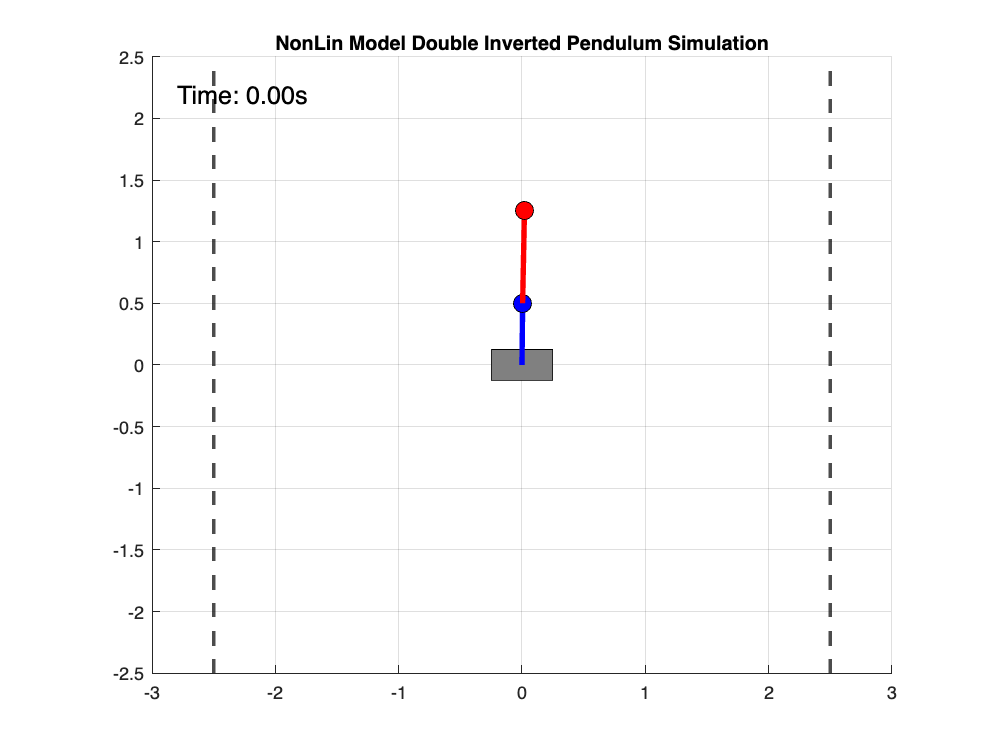

% Part 1. (4 pts) Write a MATLAB program, using handle graphics, 
% that animates the pendulum motion.
% Set the input force to zero and simulate the system behavior starting from the initial state


%% DIPC NON-LINEAR SIMULATION
close all;

% fist create sys model with all parameters
% System function into an  MATLAB function
f_handle = matlabFunction(f, 'Vars', {state_vector, u});

%Simulation params
tfinal = 10;

% smalstep size important for smooth simulation
%other optinon better solver for exp. ode45
dt = 0.01;
x_min = -2.5;
x_max = 2.5;

%Initial Conditions
x_vec = [0; 0.01; 0.02; 0; 0; 0]; 

%Graphics and Video Initialization 
cart_width = 0.5; 
cart_height = 0.25;
figure; 
ax = gca;
axis([-3 3 -2.5 2.5]); grid on;
set(ax, 'DataAspectRatio', [1 1 1]);
title('NonLin Model Double Inverted Pendulum Simulation');
x_cart = x_vec(1); y_cart = 0;
x_m1 = x_cart + l1_val * sin(x_vec(2)); y_m1 = l1_val * cos(x_vec(2));
x_m2 = x_m1 + l2_val * sin(x_vec(3)); y_m2 = y_m1 + l2_val * cos(x_vec(3));
cart = rectangle(ax, 'Position', [x_cart - cart_width/2, y_cart - cart_height/2, cart_width, cart_height], 'FaceColor', [0.5 0.5 0.5]);
xline(ax, x_min, 'k--', 'LineWidth', 2); xline(ax, x_max, 'k--', 'LineWidth', 2);
bar1 = line(ax, 'XData', [x_cart, x_m1], 'YData', [y_cart, y_m1], 'LineWidth', 3, 'Color', 'b');
mass1 = line(ax, 'XData', x_m1, 'YData', y_m1, 'Marker', 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
bar2 = line(ax, 'XData', [x_m1, x_m2], 'YData', [y_m1, y_m2], 'LineWidth', 3, 'Color', 'r');
mass2 = line(ax, 'XData', x_m2, 'YData', y_m2, 'Marker', 'o', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
time_text = text(ax, -2.8, 2.2, 'Time: 0.00s', 'FontSize', 14);
vidObj = VideoWriter('dipc_nonlinear_simulation.mp4', 'MPEG-4');
vidObj.FrameRate = 1/dt;
open(vidObj);

%Sim Loop
for t = 0:dt:tfinal

    u_input = 0;
    
    % Calculate x_dot in each step
    x_dot = f_handle(x_vec, u_input);
   
    % Update state
    x_vec = x_vec + x_dot * dt;
    
    % Boundary check --> I did that so the cart stays in the figure and real world is limeted too ;D 
    if x_vec(1) >= x_max
        x_vec(1) = x_max;
        if x_vec(4) >= 0
            x_vec(4) = 0; 
        end
    elseif x_vec(1) <= x_min
        x_vec(1) = x_min;
        if x_vec(4) <= 0
            x_vec(4) = 0;
        end
    end
    
    % Update Graphics
    x_cart = x_vec(1);
    theta1 = x_vec(2);
    theta2 = x_vec(3);
    x_m1 = x_cart + l1_val * sin(theta1);
    y_m1 = l1_val * cos(theta1);
    x_m2 = x_m1 + l2_val * sin(theta2);
    y_m2 = y_m1 + l2_val * cos(theta2);

    set(cart, 'Position', [x_cart - cart_width/2, y_cart - cart_height/2, cart_width, cart_height]);
    set(bar1, 'XData', [x_cart, x_m1], 'YData', [y_cart, y_m1]);
    set(mass1, 'XData', x_m1, 'YData', y_m1);
    set(bar2, 'XData', [x_m1, x_m2], 'YData', [y_m1, y_m2]);
    set(mass2, 'XData', x_m2, 'YData', y_m2);
    set(time_text, 'String', sprintf('Time: %.2fs', t));
    drawnow;
    frame = getframe(gcf);
    writeVideo(vidObj, frame);
end


%Cleanup
close(vidObj);
disp('sim done . Video saved  dipc_nonlinear_simulation.mp4');











